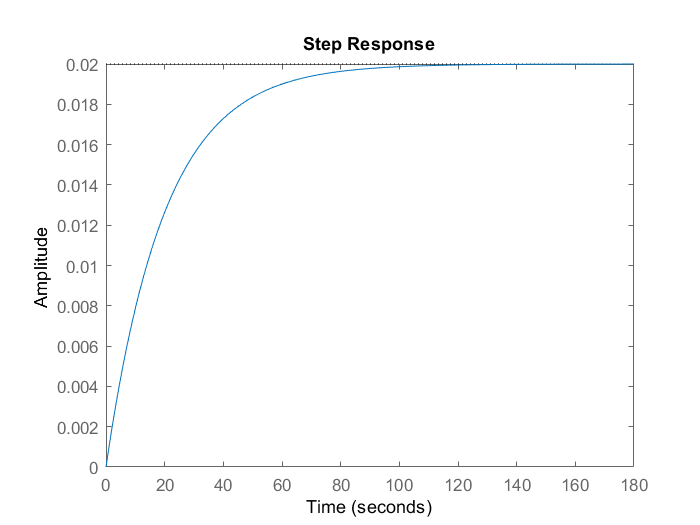

num=[1];
den=[1000 50];
F=tf(num,den);
%rise time before adding P controller
step(F);

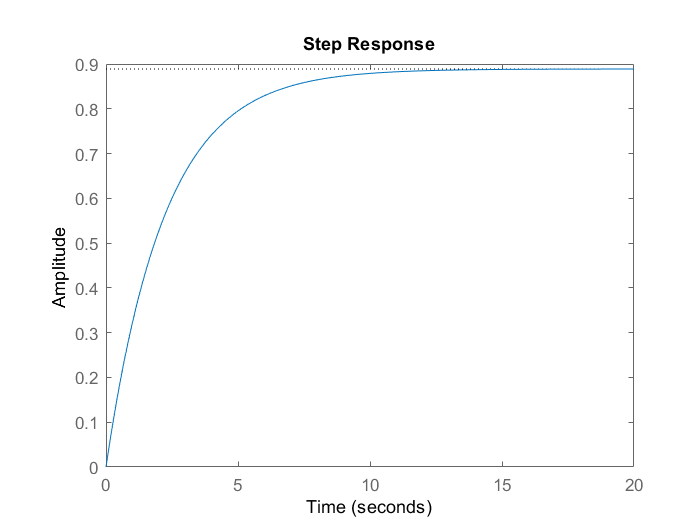

stepinfo(F);
%rise time after adding P controller
kp=400;%trial&error kore ei efficient value ber korte hobe
U=kp*F;
Y=feedback(U,1);
step(Y)

stepinfo(Y)

ans = struct with fields:
        RiseTime: 4.8822
    SettlingTime: 8.6935
     SettlingMin: 0.8040
     SettlingMax: 0.8889
       Overshoot: 0
      Undershoot: 0
            Peak: 0.8889
        PeakTime: 23.4352


%adding I controller
ki=4

ki = 4

C=pid(kp,ki)


C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 400, Ki = 4
 
Continuous-time PI controller in parallel form.



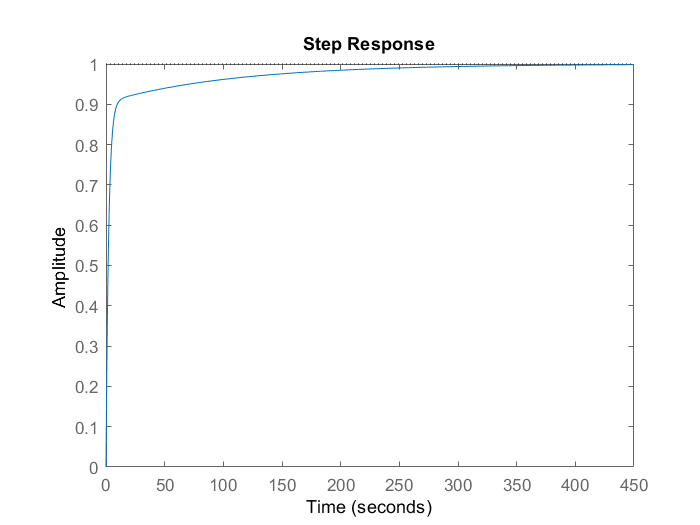

T=feedback(C*F,1);
step(T)

stepinfo(T)

ans = struct with fields:
        RiseTime: 9.3341
    SettlingTime: 171.4935
     SettlingMin: 0.9001
     SettlingMax: 0.9988
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9988
        PeakTime: 484.4049
